**Fix Random Number Stream for Reproducibility**

The example code might involve computation of random numbers at various stages. Fixing the random number stream at the beginning of various sections in the example code preserves the random number sequence in the section every time you run it, and increases the likelihood of reproducing the results. For more information, see [Results Reproducibility](https://es.mathworks.com/help/reinforcement-learning/ug/train-reinforcement-learning-agents.html#mw_cfb4600e-9d19-4e4e-89c8-2749894fee3a).

Fix the random number stream with seed `0` and random number algorithm Mersenne Twister. For more information on controlling the seed used for random number generation, see [`rng`](https://es.mathworks.com/help/matlab/ref/rng.html).

previousRngState = rng(0,"twister");

pick_place_agent_Trained

**reinforcementLearningDesigner**

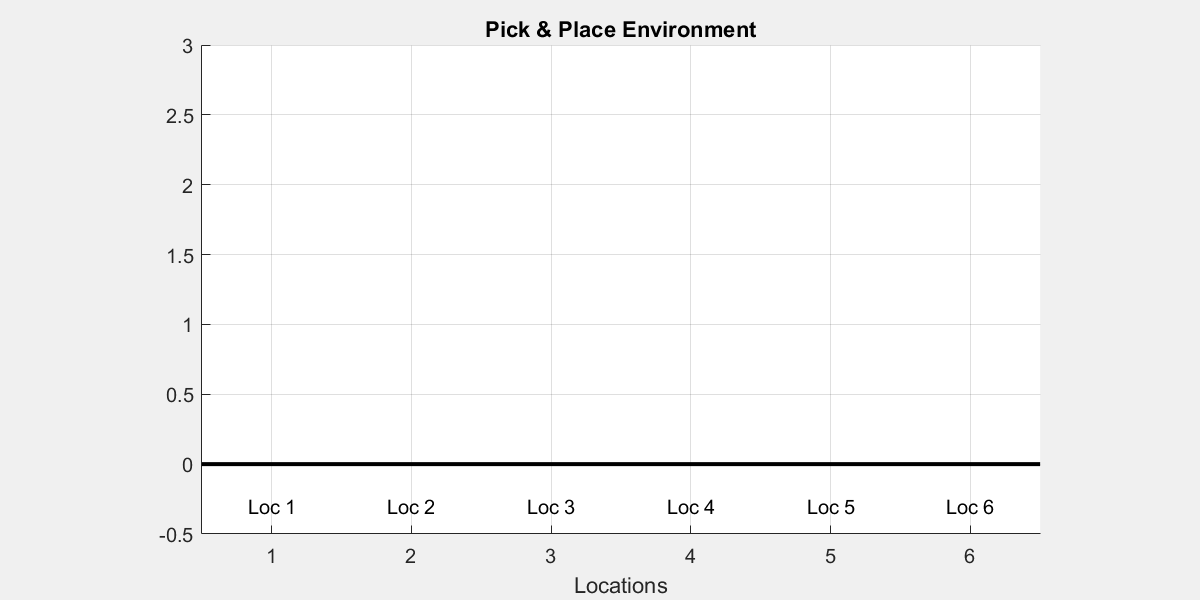

env_pick_place = PickPlaceDiscreteEnv(2, 6);

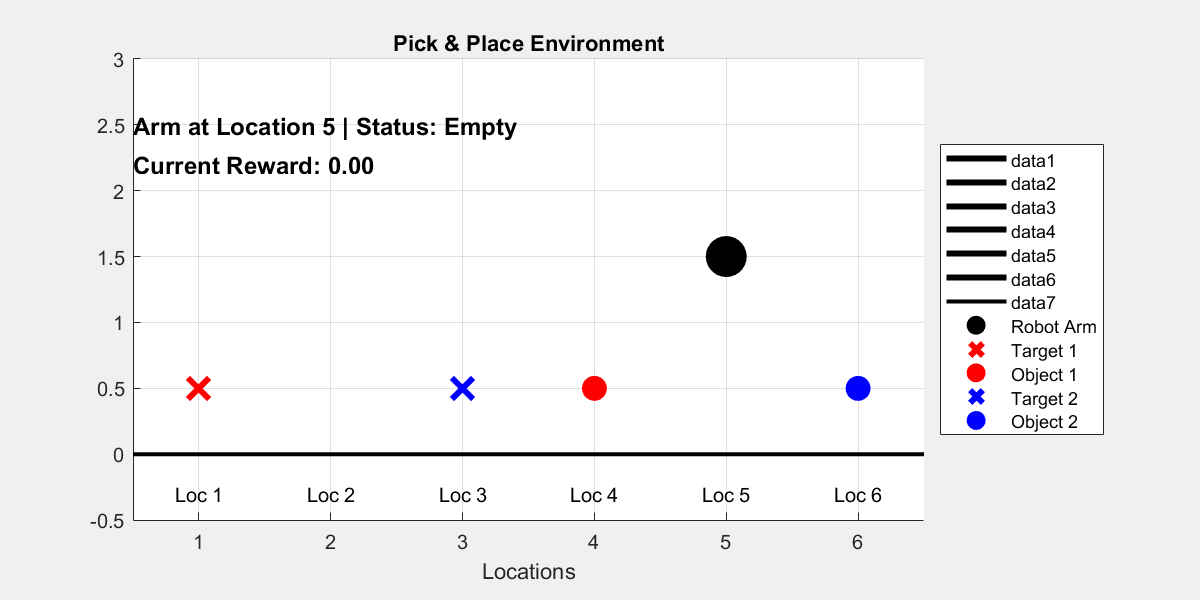

plot(env_pick_place)

xpr2 = sim(env_pick_place, agent_pick_place_v2_Trained );

Unrecognized function or variable 'agent_pick_place_v2_Trained'.

sum(xpr2.Reward)

ans = 475.0000

## HER

obsInfo = getObservationInfo(env_pick_place);
actInfo = getActionInfo(env_pick_place);
agent = rlDQNAgent(obsInfo,actInfo);

agent.AgentOptions.EpsilonGreedyExploration.Epsilon = 1.0;
agent.AgentOptions.EpsilonGreedyExploration.EpsilonMin = 0.1;
agent.AgentOptions.EpsilonGreedyExploration.EpsilonDecay = 1e-5;
agent.AgentOptions.MiniBatchSize = 128;
agent.AgentOptions.CriticOptimizerOptions.LearnRate = 5e-4;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;

    rewardFcn = @PickPlaceRewardFunc;
    isDoneFcn = @PickPlaceIsDoneFunc;
    % observation is [robot_x, robot_y, goal_x, goal_y]'
    % goal measurement: channel --- 1, indices --- 1,2
    % goal: channel --- 1, indices --- 3,4 
    goalConditionInfo = {{1, [3,4], 1, [5,6]}};
    bufferLength = 1e5;
    agent.ExperienceBuffer = rlHindsightReplayMemory(obsInfo,actInfo,...
        rewardFcn,isDoneFcn,goalConditionInfo,bufferLength);

maxEpisodes = 3000;
maxStepsPerEpisode = 10;
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxEpisodes, ...
    MaxStepsPerEpisode=maxStepsPerEpisode, ...
    Verbose=false, ...
    ScoreAveragingWindowLength=100,...
    Plots="training-progress",...
    StopTrainingCriteria="EvaluationStatistic",...
    StopTrainingValue=1.9);   

evaluator = rlEvaluator( ...
    EvaluationFrequency=50, ...
    NumEpisodes=10, ...
    RandomSeeds=101:110);

    trainingStats = train(agent,env_pick_place, trainOpts, Evaluator=evaluator);

## Predefined

env = rlPredefinedEnv("SimplePendulumWithImage-Discrete")

env =   SimplePendlumWithImageDiscreteAction with properties:

             Mass: 1
        RodLength: 1
       RodInertia: 0
          Gravity: 9.8100
     DampingRatio: 0
    MaximumTorque: 2
               Ts: 0.0500
            State: [2×1 double]
                Q: [2×2 double]
                R: 1.0000e-03


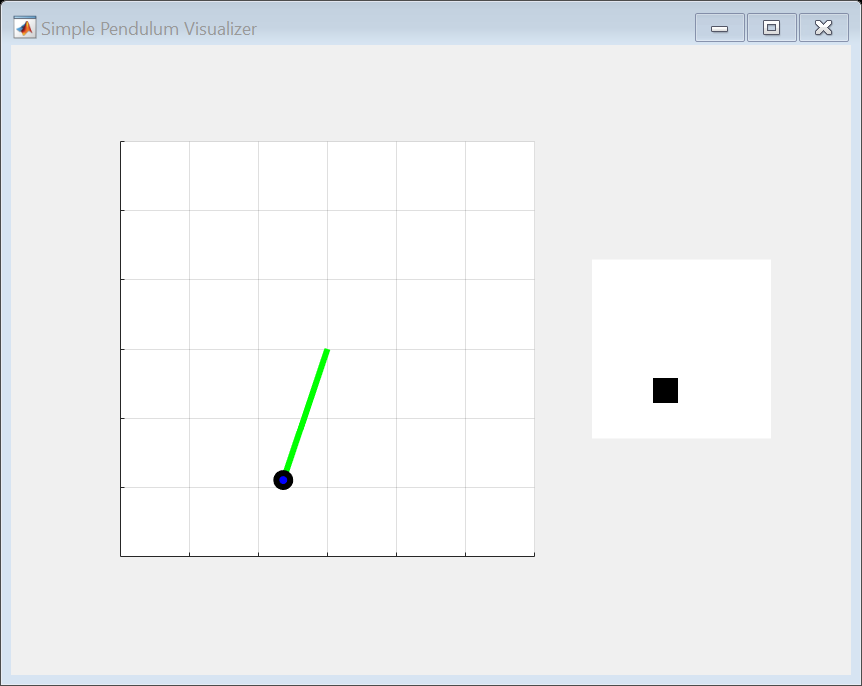

plot(env)
xpr2 = sim(env,agent2_Trained);

sum(xpr2.Reward)

ans = -4.3324e+03

`'NavigationDiscreteEnv' is used in `[`Train DQN Agent Using Hindsight Experience Replay`](matlab:matlab.internal.examples.openExample('rl/TrainDQNAgentInNavigationEnvWithHindsightReplayMemoryExample');)`.`

## Creating a random environment

rlCreateEnvTemplate("Pick_Place")

cd ai && matlab -batch "run('test_pick_place_dqn.m')"